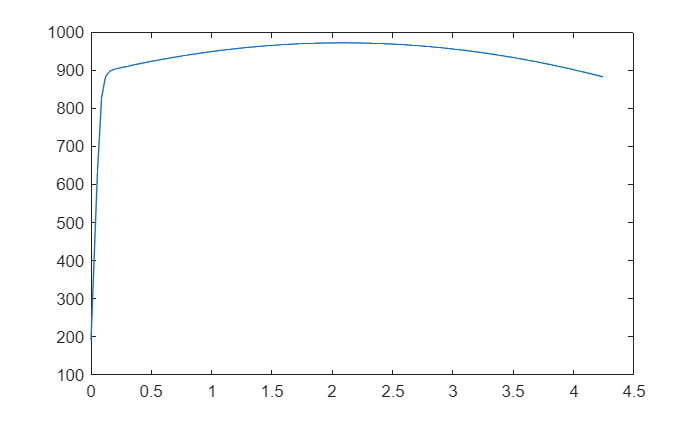

close all; clear; clc; clf;




%



Cd =  [0.15 0.15 0.42 0.25 0.175];
mCd = [0.00 0.60 1.20 1.80 4.000];


% internal_ballistics(N,L_0,r_f,r_i,rho_p,a_0,n)

[mass,chamber,t,accel,velocity,height] = internal_ballistics(4,8,2.375,1,0.065,0.03,0.35);
plot(t,chamber)

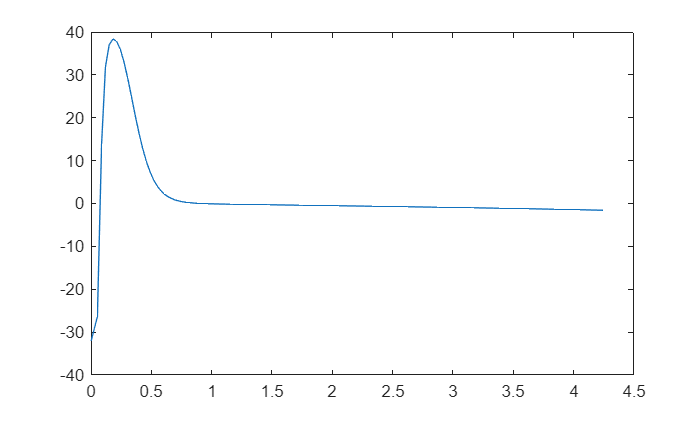

plot(t,accel)

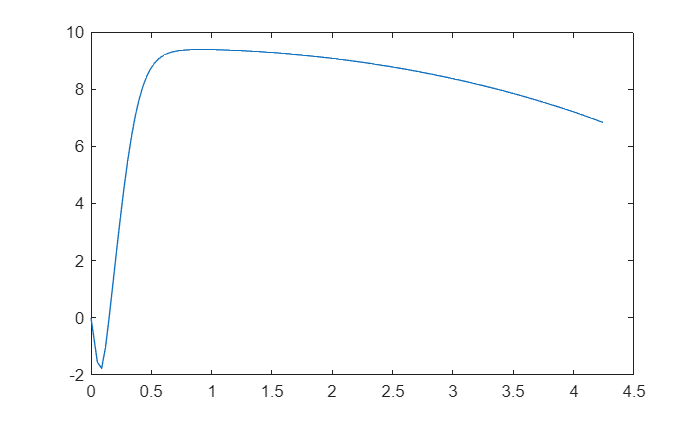

plot(t,velocity)

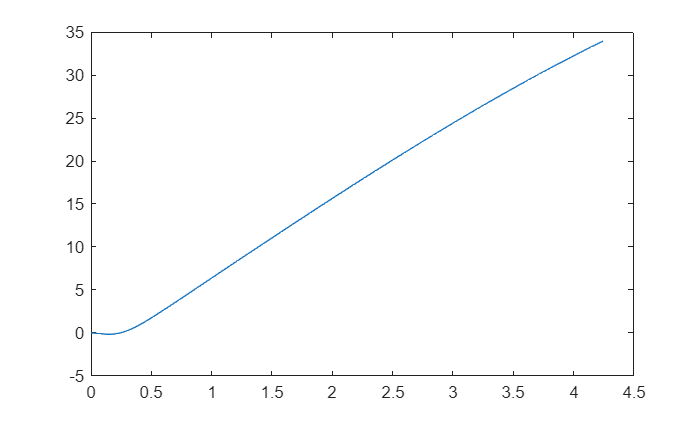

plot(t,height)



function [mpropelent,pressure_chamber,time,acc,vel,height] = internal_ballistics(N,L_0,r_f,r_i,rho_p,a_0,n)

cstar = 5210;
w_step = 0.01;
w(1) = 0;
pressure_chamber(1) = (rho_p*a_0*N * 2*pi*( r_f^2 - (r_i).^2 + (r_i).*L_0)*cstar)^(1/1-n);
time(1) = 0;
A_t(1) = 1;
exit_area = 4;
gamma = 1.25;

acc(1) = -32.2;

vel(1) = 0;

height(1) = 0;

cf(1) = 1.5;



temp_amb(1) = 518;
ambient_pressure(1) = 14.69241;

Cd =  [0.15 0.15 0.42 0.25 0.175];
mCd = [0.00 0.60 1.20 1.80 4.000];

rho_air(1) = 0.07579;

m_i = rho_p * N * pi*(r_f^2 - r_i^2) * (L_0) + N*(L_0 + 0.125) * 0.25 + 40 + 1;

for iteration = 1:1000

w(iteration + 1) = 0 + w_step*iteration;

A_b(iteration) = N * 2*pi*( r_f^2 - (r_i+w(iteration)).^2 + (r_i+w(iteration)).*(L_0 - 2.*w(iteration)));

r(iteration) = a_0 * (pressure_chamber(iteration))^n;

dt = w_step/r(iteration);

A_t(iteration+1) = ((4/pi)^0.5 + 0.000087 * dt*pressure_chamber(iteration))^2*pi/4;


pressure_chamber(iteration + 1) = (rho_p * r(iteration)*A_b(iteration)*cstar/A_t(iteration))^(1/1-n);

time(iteration+1) = time(iteration) + dt;

mpropelent(iteration) = rho_p * N * pi*(r_f^2-(r_i+w(iteration))^2) * (L_0 - 2*w(iteration));

arearatio = exit_area / A_t(iteration);


mach = abs(vel(iteration)/sqrt(1.4*1545.3/28.97*32.2*temp_amb(iteration)));

acc(iteration+1) = cf(iteration) * A_t(iteration) * pressure_chamber(iteration)/(m_i - mpropelent(iteration)) -32.2 - interp1(mCd,Cd,mach)*32.2*(0.5*rho_air(iteration)*vel(iteration)^2)*(pi*6.19^2)/(m_i - mpropelent(iteration));

temp_amb(iteration+1) = -0.0036 * height(iteration) + 518; 

rho_air(iteration+1) = (0.00000000001255)*vel(iteration)^2 -(0.0000019453)*vel(iteration) + 0.07579;

vel(iteration + 1) = (acc(iteration+1) + acc(iteration))/2 * dt + vel(iteration);

height(iteration + 1) = (vel(iteration + 1) + vel(iteration)) /2 * dt+ height(iteration);

pcOverpa = pressure_chamber(iteration)/ambient_pressure(iteration);
papc = pcOverpa^(-1);
pepc = (1+(gamma-1)/2 * mach^2)^((gamma-1)/gamma);


cf(iteration+1) = (2*gamma^2/(gamma-1)   *   (2/(gamma+1))^((gamma+1)/(gamma-1))   *   (1 - (pepc)^((gamma-1)/gamma))) + (pepc-papc)*arearatio;


ambient_pressure(iteration + 1) = -4.272981*10^(-14) * height(iteration)^3 + 0.000000008060081*height(iteration)^2 + 0.0005482655*height(iteration) + 14.69241;


if (r_i + w(iteration)) >= r_f  
    break;
elseif (L_0 - 2*w(iteration)) <= 0
    break;
end

end

end



